# Project 2: Recognition of digits from handwriting samples

**PREPROCESSING STEPS OF OUR DATASET**

- **We used preprocessing programs made available by NIST to extract normalized bitmaps of handwritten digits from a preprinted form. From a total of 43 people, 30 contributed to the training set and different 13 to the test set. 32x32 bitmaps are divided into nonoverlapping blocks of 4x4 and the number of on pixels are counted in each block. This generates an input matrix of 8x8 where each element is an integer in the range 0..16. This reduces dimensionality and gives invariance to small distortions.**

- **Data Source: Handwritten digit images are extracted from a preprinted form. These images are typically grayscale and represent digits written by individuals.**

- **Division into Blocks: The normalized images are divided into nonoverlapping blocks of size 4x4 pixels. This division helps in capturing local patterns and features within the digit images.**

- **Feature Extraction: For each block, the number of "on" pixels (i.e., pixels with non-zero intensity) is counted. This counting operation generates a feature matrix of size 8x8, where each element represents the count of "on" pixels in a 4x4 block.**

- **The counting operation is performed to quantify the presence of features (e.g., edges, shapes) within each block.**

- **This counting process generates an 8x8 feature matrix, where each element represents the count of "on" pixels within a corresponding 4x4 block. counting "on" pixels with non-zero intensity refers to identifying and quantifying the presence of illuminated areas or features within an image. These features could include edges, shapes, textures, or other visually significant elements that contribute to the image's content.**

- **Dimensionality Reduction: The feature matrix is of size 8x8, which provides a compact representation of the digit images while preserving important information about their structure and content. This dimensionality reduction helps in reducing computational complexity and memory requirements for subsequent processing steps.**

***N.B. *****In feature extraction method, counting the number of "on pixels" (0 - 16) in each block of the bitmap allows to capture the spatial distribution and density of the ink or intensity variations within the digit image. This count provides useful information for characterizing and distinguishing different handwritten digits, even if it does not directly capture the specific intensity levels of individual pixels.(0 - 255)**

## PART ONE

## 1. Read the data

## 1.1 Import the data

opts = delimitedTextImportOptions("NumVariables", 14);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = " ";

% Specify column names and types
opts.VariableNames = ["Two", "versions", "of", "this", "database", "available", "VarName7", "VarName8", "VarName9", "VarName10", "VarName11", "VarName12", "VarName13", "VarName14"];
opts.VariableTypes = ["string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string"];

% Specify file level properties
% % % % % % % % % opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";
opts.ConsecutiveDelimitersRule = "join";
opts.LeadingDelimitersRule = "ignore";

% Specify variable properties
opts = setvaropts(opts, ["Two", "versions", "of", "this", "database", "available", "VarName7", "VarName8", "VarName9", "VarName10", "VarName11", "VarName12", "VarName13", "VarName14"], "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["Two", "versions", "of", "this", "database", "available", "VarName7", "VarName8", "VarName9", "VarName10", "VarName11", "VarName12", "VarName13", "VarName14"], "EmptyFieldRule", "auto");

% Import the data
readme = readtable("C:\Program Files\MATLAB\R2023b\toolbox\digits\readme.txt", opts);

## Clear temporary variables

clear opts
warning('off','all');

## 1.2 Load the data

Load the optdigits.tra and optdigits.tes file. Save the features (items 1-64) and Labels(item 65). 

% Load your data (assuming 'optdigits.tra' and 'optdigits.tes' files are available)
loaded_data_tra = load('optdigits.tra');
loaded_data_tes = load('optdigits.tes');
% Extract features and labels for training data
tra_x = loaded_data_tra(:, 1:end-1);  % Features
tra_y = loaded_data_tra(:, end);      % Labels

% Extract features and labels for testing data
tes_x = loaded_data_tes(:, 1:end-1);  % Features
tes_y = loaded_data_tes(:, end);      % Labels

% Combine training and testing data
all_x = [tra_x; tes_x]; % Features
all_y = [tra_y; tes_y]; % Labels: 0 to 9

## 2. Display the dataset by using the PCA

### **   2.1. Implement pca function**

### **   2.2. Visualize the data by using eigenvalues of the covariance matrix**

## 2.1 Implement PCA function

[coeff, score, latent,explained] = pca(all_x);

% 'coeff' contains the principal component coefficients.
% 'score' contains the principal component scores.
% 'latent' contains the eigenvalues of the covariance matrix.


## 2.2 Visualize the data by using eigenvalues of the covariance matrix

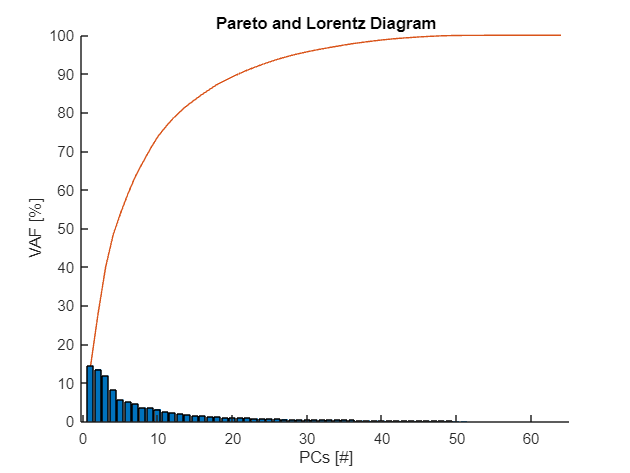

% plot the eigenvalues of the covariance matrix to decide how many principal components to retain.

figure

bar(100.*latent./sum(latent))

hold on

line(1:length(latent),100.*cumsum(latent)./sum(latent))
title("Pareto and Lorentz Diagram")
xlabel('PCs [#]')
ylabel('VAF [%]')
ylim([0 100])
box off

## 2.3 Project the original data into the reduced space.

Choose the number of principal components you want to retain based on the VAF plot.

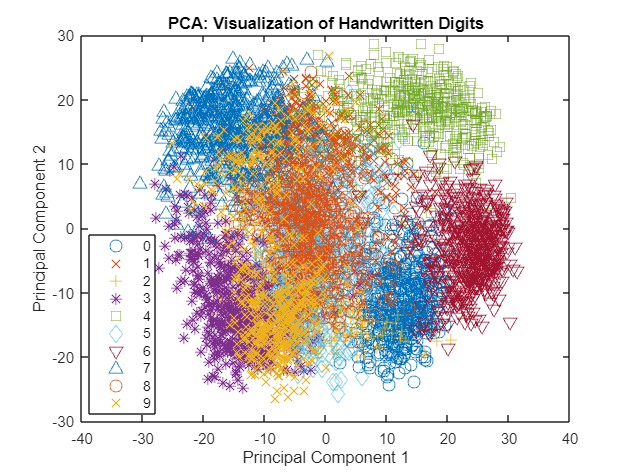

% part one
% Create a scatter plot to visualize the data in reduced space

figure;
gscatter(score(:, 1), score(:, 2), all_y, [], 'ox+*sdv^', 8);
title('PCA: Visualization of Handwritten Digits');
xlabel('Principal Component 1');
ylabel('Principal Component 2');
legend('Location', 'Best');

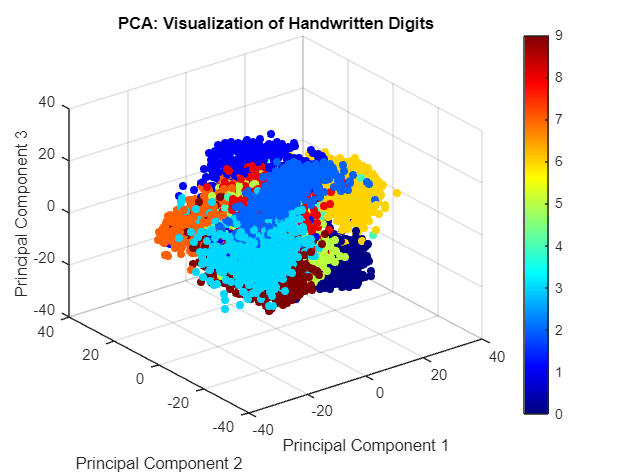

% part two
% Create a 3D scatter plot to visualize the data in reduced space

figure;
scatter3(score(:, 1), score(:, 2), score(:, 3), 30, all_y, 'filled');
title('PCA: Visualization of Handwritten Digits');
xlabel('Principal Component 1');
ylabel('Principal Component 2');
zlabel('Principal Component 3');
colormap('jet');
colorbar;

## PART TWO

## 3. Partition the dataset into training and test set

## 3.1 Partition the dataset

### **By using MATLAB function randperm or cvpartition.**

### **   1. Random Permutation(optional)**

### **   2. Cross-Validation Partition**

### **   3. Train naive bayes classifier**

% initialize digits
digits = [0 1 2 3 4 5 6 7 8 9];

% Number of samples
N = size(all_x, 1);
cv_digits = cvpartition(all_y, 'HoldOut',0.2);

% Initialize training and test sets
trainIdx = training(cv_digits);
testIdx = test(cv_digits);

% Training set
Xtr = all_x(trainIdx, :);
Ytr = all_y(trainIdx);

% Test set
Xte = all_x(testIdx, :);
Yte = all_y(testIdx);


## 4.Classification

classlist = ["Naive Bayes","Logistic Regression","LDA"];

% for all confusion matrices
f1 = figure ;

% for all roc curves
f2 = figure ;

for cl = 1:length(classlist)

    classif = classlist(cl);

    switch (classif)


## 4.1 Naive bayes classifier

        case "Naive Bayes"

            % Train Naive Bayes classifier using training set
            NBmodel = fitcnb(Xtr, Ytr,"DistributionNames","mvmn");


**# As we now from the begning that the extracted features represent counts of pixel intensities within blocks and are discrete integer values in the range 0 to 16, the Multinomial distribution seems appropriate for modeling this type of data. The Multinomial distribution is suitable for discrete data where each feature represents the frequency of occurrence of a category (in this case, pixel intensity levels).**

**# Kernel distirbution is more suitable for continous data, If my pixel values are continuous (e.g., grayscale values ranging from 0 to 255), you might consider using a kernel distribution. Kernel density estimation can effectively model continuous data by estimating the underlying probability density function.**

**# And we checked the performance of each distribution and the performance of the classifier with multinomial distribution is more accurate.**

            % ################# calculate posterior for TRAIN and TEST ################

            % Make predictions on training set
            [label_tr, Posterior_tr, Cost_tr] = predict(NBmodel, Xtr);

            % Make predictions on test set
            [label_te, Posterior_te, Cost_te] = predict(NBmodel, Xte);


## 4.2 logistic Classifier

        case "Logistic Regression"

            % train Logistic Regression classifier using training set
            LRmodel = fitmnr(Xtr, Ytr,'ModelType','hierarchical');

            % ################# calculate posterior for TRAIN and TEST ################

            % Make predictions on training set
            [label_tr, Posterior_tr, Cost_tr] = predict( LRmodel, Xtr);
            % Make predictions on test set
            [label_te, Posterior_te, Cost_te] = predict( LRmodel, Xte);


## BONUS 

## 4.3 LDA classifier

## Definition :

**In the context of multi-class classification, the typical approach is to train multiple binary classifiers, each distinguishing between one class and the rest. For example, in the OvR approach, you would train *****k***** binary classifiers where *****k***** is the number of classes. Each classifier is trained to discriminate between one class and all the others. During inference, the class with the highest output from these classifiers is chosen as the predicted class.**

**In MATLAB, the fitcdiscr function can be used for multi-class LDA classification. When you provide it with a multi-class response variable (i.e., labels), it automatically handles the multi-class scenario by internally using the OvR strategy.**

**When you call fitcdiscr with your training data (**`Xtr`**) and corresponding labels (**`Ytr`**), the function automatically learns to distinguish between the different classes (digits in my case) based on the features( pixels) provided. It estimates the parameters of the multivariate Gaussian distributions for each class and determines decision boundaries that best separate the classes in the feature space.**

**During the training process, the LDA classifier learns the statistical properties of each class and how they differ from one another. It computes the ****mean**** and ****covariance matrix**** for each class, which are used to model the class-conditional probability distributions.**

**One-Versus-Rest (OvR) Approach:**

- **In the OvR approach, instead of training a single classifier to predict all ten digits at once, you train ten separate binary classifiers.**

- **Each binary classifier is trained to answer a specific question: " Is this example/ sample/ digit 0 ? " " Is this example digit 5 ? " ...**

- **So, you have one classifier for each digits.**

- **This all proceses are done automatically by using fitcdiscr function.**

**In summary, the OvR approach breaks down a multi-class classification problem into multiple binary classification problems, making it easier for the classifiers to learn and make predictions on each class independently.**

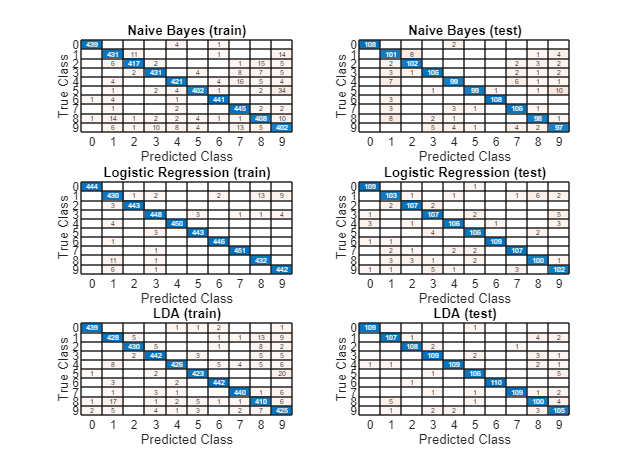

          
        case "LDA"
           
            % Train the LDA classifier using training set
            LDAmodel = fitcdiscr(Xtr, Ytr,"DiscrimType","pseudolinear"); % "pseudolinear" option refers to performing linear discriminant analysis (LDA) with the assumption of unequal class covariance matrices.

            % ################# calculate posterior for TRAIN and TEST ################

            % Make predictions on training set
            [label_tr, Posterior_tr, Cost_tr] = predict(LDAmodel, Xtr);

            % Make predictions on test set
            [label_te, Posterior_te, Cost_te] = predict(LDAmodel, Xte);

    end

## 5. Compute Confusion Matrix For All Classifier

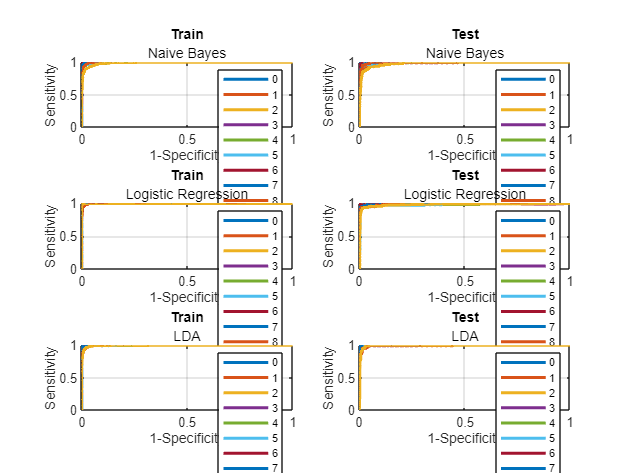

    figure(f1)

    % ############# TRAIN ###############

    subplot(length(classlist),2,2*cl-1)
    confusionchart(Ytr, label_tr);
    title(sprintf('%s (train)',classlist(cl)));

    % ############# TEST ##############

    subplot(length(classlist),2,2*cl)
    confusionchart(Yte, label_te);
    title(sprintf('%s (test)',classlist(cl)));



## 6. Compute AUC and plot ROC graph for all classifier

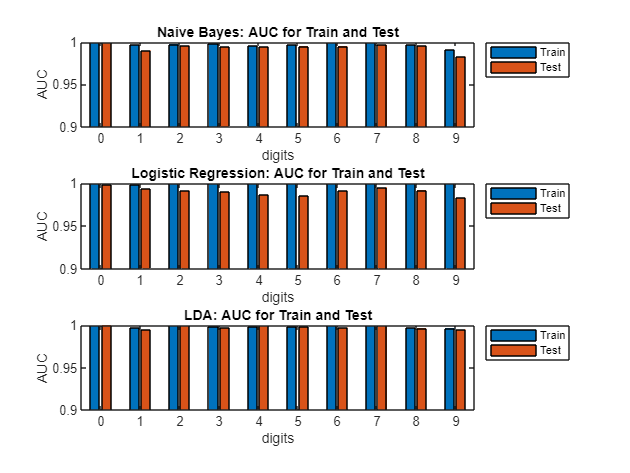

    figure(f2)

    % Initialize variables to store ROC curve data and AUC values for each class
    fpr_tr_all = cell(length(digits), 1); % false positive rate for training
    tpr_tr_all = cell(length(digits), 1); % true positive rate for training

    fpr_te_all = cell(length(digits), 1); % false positive rate for test
    tpr_te_all = cell(length(digits), 1); % true positive rate for test

    auc_tr_all = zeros(length(digits),1); % intialize AUC for training set
    auc_te_all = zeros(length(digits),1); % intialize AUC for test set

    % Loop over each class

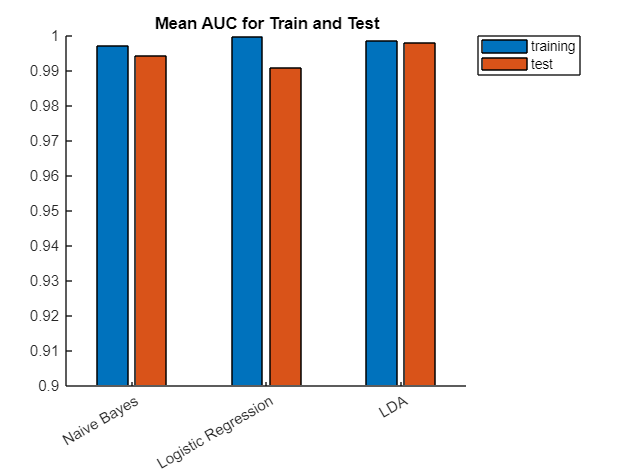

    for i = 1:length(digits)
        % Extract posterior probabilities for the current class
        class_positive_tr = Posterior_tr(:, i); % Here, we choose positive digit class in every loop for training.
        class_positive_te = Posterior_te(:, i); % Here, we choose positive digit class in every loop for test.

        % Compute ROC curve and AUC for training set for the current class
        [fpr_tr_all{i}, tpr_tr_all{i}, ~,auc_tr_all(i)] = perfcurve(Ytr, class_positive_tr, digits(i));

        % Compute ROC curve and AUC for test set for the current class
        [fpr_te_all{i}, tpr_te_all{i}, ~,auc_te_all(i)] = perfcurve(Yte, class_positive_te, digits(i));
    end



    % ######################TRAIN#######################


    for i = 1:length(digits)
        subplot(length(classlist),2,2*cl-1)
        plot(fpr_tr_all{i}, tpr_tr_all{i}, 'LineWidth', 2);
        hold on;
    end

The best classifier is: LDA!


    xlabel('1-Specificity');
    ylabel('Sensitivity');
    title(sprintf('Train'),classlist(cl));
    legend(cellstr(num2str(digits(:))));
    grid on;
    hold off;

    % #######################TEST######################

    for i = 1:length(digits)
        subplot(length(classlist),2,2*cl)
        plot(fpr_te_all{i}, tpr_te_all{i}, 'LineWidth', 2);
        hold on;
    end
    xlabel('1-Specificity');
    ylabel('Sensitivity');
    title(sprintf('Test'),classlist(cl));
    legend(cellstr(num2str(digits(:))));
    grid on;
    hold off;

    AllAUC_tr(cl,:)= auc_tr_all' ;
    AllAUC_te(cl,:)= auc_te_all' ;

end

## 7. Plot AUC using bar graph for all classifier


figure;
for cl = 1 : length(classlist)
    subplot(length(classlist), 1, cl);
    bar([AllAUC_tr(cl,:)', AllAUC_te(cl,:)']);
    xlabel('digits');
    ylabel('AUC');
    ylim([0.9 1]);
    title(sprintf('%s: AUC for Train and Test', classlist(cl)));
    legend('Train', 'Test');
    legend('Location','bestoutside')
    xticks(1:length(digits));
    xticklabels(cellstr(num2str(digits(:))));
end

## 8. Compare the AUC of all classifier in one bar graph

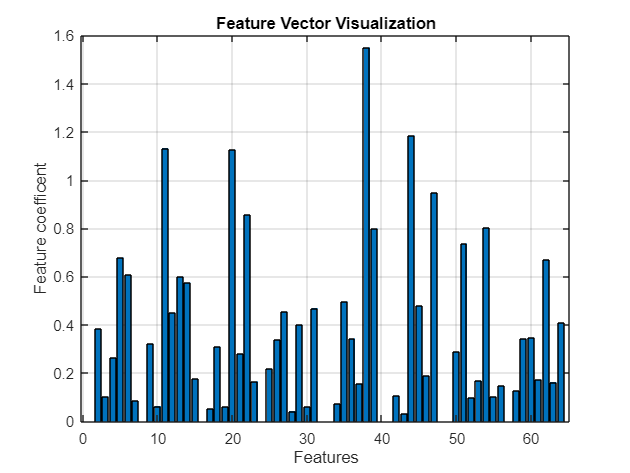

Mean_ALLAUC_tr = mean(AllAUC_tr,2);
Mean_ALLAUC_te = mean(AllAUC_te,2);

figure;
bar([Mean_ALLAUC_tr,Mean_ALLAUC_te])
ylim([0.9 1]) % This line sets the y-axis limits to be between 0.9 and 1, since AUC typicaly ranges from 0.9 - 1.
classtypes ={'Naive Bayes','Logistic Regression','LDA'}; % This line defines a cell array classtypes containing the names of the classifiers.
xticklabels(classtypes) % The xticklabels function assigns the labels from classtypes to the x-axis ticks of the bar graph.
xticks(1:length(classtypes)) % Assign the classtypes with evenly spaced integer values, so, the classifiers are proportionaly assined on the X-axis.
title('Mean AUC for Train and Test');
box off

legend({'training','test'}) % left side of the bar is 'training' and right side of the bar is 'test'
legend('Location','bestoutside') %position the legends on the upper right side corner

ALLAUC_mean = [Mean_ALLAUC_tr,Mean_ALLAUC_te];
[m,i]=max(ALLAUC_mean(:,2)); % This command finds the maximum value in the second column of the matrix AllAUC, which contains the AUC values for the test dataset.
%The function max returns two outputs: the maximum value (m) and the index of that value (i).

disp(sprintf('The best classifier is: %s!',classtypes{i}))

## 8. Representing the importantance of each feature (discriminatory power) for discrimination of the Digit 1 and Digit 8.

**LETS do this part by using two approaches.**

**8.1 Direct calculation : By finding the LDA vector ' W ' manually by using local function ( ldaclass_1 and  ldaclass_one)**

**8.2 By using built in MATLAB function fitcdiscr which is used to train our data using LDA classifier.**

## 8.1. Direct calculation : by using LDA vector W

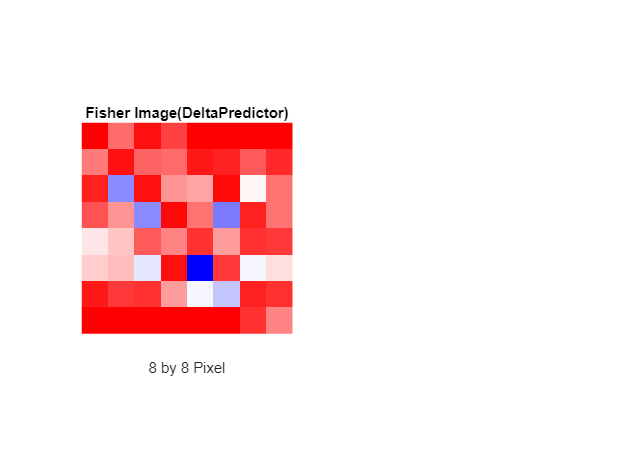

% on this section we will see, which features are more important to discriminate
% between the two problematic digits ( digit 1 and digit 8 ) which we saw on the section 5 of confusion matrix. By designing a new
% function (w1 & w2), which calculates the LDA vactor w, which maximize the
% separation between this two classes.[ this function trys to maximize the
% 'between class' scatter by minimizing 'within class' scatter matrix(covariance).]

% In both classes there are a features which are colinear/linearly dependent, as a result
% the inverse computation couldn't be possible, since the matrix is

% singular/ Deificient Rank/.
% to avoid these problem we have two options
% 1. Regularization
% 2. Feature selection : before computing the " within class scatter matrix "

**OPTION 1 . REGULARIZATION : Regularization involves adding a small constant value (often denoted as λ) to the diagonal elements of the covariance matrix. This helps ensure that  the covariance matrix is non-singular by increasing the diagonal elements slightly, effectively making them positive-definite. The regularization term helps stabilize the inversion process and prevents numerical instability. and since my goal is to visualize the importance of each feature Regularization would be the best option to this problem.**

- **We introduce a regularization parameter lambda, which determines the strength of regularization.**

- **We add a small multiple of the identity matrix (lambda * eye(size(Sw1))) to each covariance matrix to ensure it is non-singular.**

- **We compute the combined regularized covariance matrix (Sw_reg) by adding the regularized covariance matrices.**

- **We use the pinv function to compute the pseudo-inverse of the regularized covariance matrix.**

- **Finally, we compute the LDA vector (w) using the regularized pseudo-inverse and normalize it to ensure its unit length.**

**OPTION 2. FEATURE SELECTION : before proceed to computing the between class matrix and within class matrix, lets remove the features which has zero variance (those features with zero variance are colinear each other) from both classes. This helps to make within class scatter matrix to be non singular/invertible.     **

## Option 1 : Using Regularization

w1 = ldaclass_1(all_x, all_y);

Features with zero variance found. Removing...
Removed features: 1   8   9  16  24  32  33  40  41  48  49  57
Features with zero variance found. Removing...
Removed features: 1   8  16  24  25  32  33  40  41  48  49  57


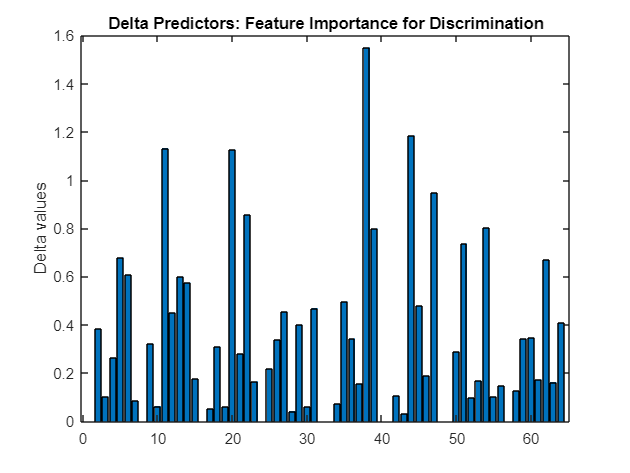

% Step 1: Filter the dataset
% Find indices of samples labeled as 1 or 8
indices_1 = find(all_y == 1);
indices_8 = find(all_y == 8);
indices_1_8 = [indices_1 ; indices_8] ;
% Filter features and labels based on selected indices above
features_1 = all_x(indices_1 , :); % all filterd features for digit 1.
features_2= all_x(indices_8, :); % all filterd features for digit 8.
features1_2= [features_1 ; features_2] ;
labels= all_y(indices_1_8); % all filterd labels for both digit 1 and 8.

% projection of the data onto the LDA vector 'W', which maximize the
% separation between the two classes( digit 1 and digit 8.)

Ztr = features1_2 .* w1' ;

% train the model by using the projected data

w1_LDA = fitcdiscr(Ztr,labels,"DiscrimType","pseudolinear");

% option 1 to visualize the feature weights by using the Bar graph

% Plot the LDA vector (feature weights)
figure;
bar(w1_LDA.DeltaPredictor);
ylabel('Feature coefficent');
xlabel('Features')
title('Feature Vector Visualization');
grid on;
% option 2 to visualize the fisher image using DeltaPredictor
DeltaPredictor=w1_LDA.DeltaPredictor;
figure;
subplot(1,2,1)
DeltaPredictor_reshaped = reshape(DeltaPredictor, [8, 8]);

cmap= zeros(64,3);
cmap(:,1) = [ones(32,1); linspace(1,0,32)'];
cmap(:,2) = [linspace(0,1,32)'; linspace(1,0,32)'];
cmap(:,3) = [linspace(0,1,32)'; ones(32,1)];

imshow(DeltaPredictor_reshaped,[]); % Display the reshaped image.
title('Fisher Image(DeltaPredictor)');
xlabel('8 by 8 Pixel');
colormap(cmap)

% % option 3 to visualize the fisher image using the LDA vecor W1( from direct calculation ).
%
% w11LDA_reshaped = reshape(w1, [8, 8]);  % Reshape the LDA vector to 8 by 8 image..
% % Visualize the Fisher image
% subplot(1,2,2)
% imshow(w11LDA_reshaped);  % Display the reshaped LDA vector as an image
% colormap(cmap)
% title('Fisher Image(Direct calculation : LDA vector w1)');
% xlabel('8 by 8 Pixel');


**From this feature image we can understand that, pixels with higher magnitude (Blue image) are more important to discriminate, **

**pixels with magnitude closer to 0 (Red  image) are less important to discriminate.**

**for example : **

- ** feature 38 or X38 is the most important feature to discriminate the two digit.**

- ** feature 1, 8, 16, 24, 32, 33, 40, 41, 48, 49 and 57 are not significant for discriminating the digits.**

## option 2: Using Feature selection

w2= ldaclass_onee(all_x,all_y);

## Conclusion : on option 1 and option 2

** If we compared the coefficent of DeltaPredictors of the features which are removed from option 2 ( 1, 8, 16, 24, 32, 33, 40, 41, 48, 49, 57 ) and the same features on option 1, we see that the magnitude of the coefficent (or the color) for these removed features are close to zero (Dark Red in teh Fisher image).**

- **after we remove the features our features deacrease to 52 from 64. As a result we can't project our orginal data onto it, since the array size incompatible, but we understood that  in the case of feature selection / dimensionality reduction / our model might become overfit.**

- **For example : if we checked the value of x9 and x25 on the fisher image thay are significant on discriminating the two digtis. so, if we removed these feature from our data during ttraining, it may become difficult for some new test samples during prediction time.**

## 8.2.  By using fitcdiscr function with Delta predictor.

**Here, I directly feed my fitcdiscr function, with my orginal data digit 1 and digit 8 to train it, with out projecting it to the LDA vector ' w1 '. So, in this case the function do the whole process by it self. **

- **But, in topic 8.1  we find the LDA vactor ' w ' by ovrselves by using some mathimatical methods, which are BETWEEN CLASS SCATTER and WITHIN CLASS SCATTER MATRIX, to calculate the maximum separation between classes (digit 1 and digit 8).**

- **On topic 8.1, option 1, After we got the LDA vector w1, we project the data onto the w1 vector then we train our model using the projected data (Ztr, labels).**

- **On topic 8.1, option 2,  after we select the features our features deacrease to 52 from 64. As a result we can't project our orginal data onto it, since the array size incompatible, but we understood that, in the case of feature selection / dimensionality reduction / our model might become overfit. (x9 & x25)                                                                                                **

% Step 1: Filter the dataset
% Find indices of samples labeled as 1 or 8
indices_1 = find(all_y == 1);
indices_8 = find(all_y == 8);
indices_1_8 = [indices_1 ; indices_8] ;
% Filter features and labels based on selected indices above
features_1 = all_x(indices_1 , :); % all filterd features for digit 1.
features_2= all_x(indices_8, :); % all filterd features for digit 8.
features1_2= [features_1 ; features_2] ;
labels= all_y(indices_1_8); % all filterd labels for both digit 1 and 8.

LDA1_2 = fitcdiscr(features1_2,labels,"DiscrimType","pseudolinear");

figure;
bar(LDA1_2.DeltaPredictor)
ylabel('Delta values')
title('Delta Predictors: Feature Importance for Discrimination');

### **In this case, I can see the magnitude of the delta values, which indicates the strength of the contribution of each feature to the classification. Larger magnitude values suggest stronger discriminatory power.**

- ** Both the Results in topic 8.1 ( the DeltaPredictors which are calculated by using direct calculation from Local function 'w1') and 8.2 are exactly the same.**

## THANK YOU!